# Normalization : explorations

This code is trying to simulate different forms of normalization that have not been used in papers

## Prep : parameters that will be used in the code

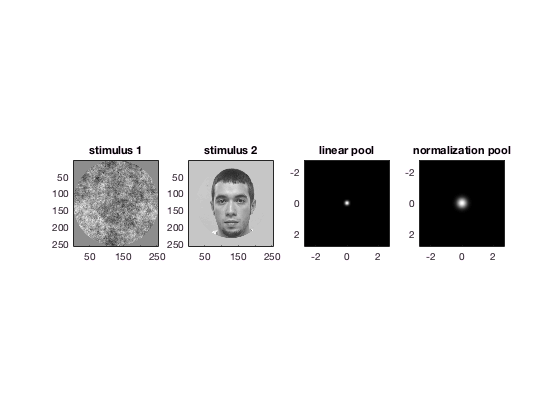

% make stimulus
stim    = {};
stim{1} = single(imread('stim_img1.png')); stim{1} = stim{1}./max(stim{1}(:));
stim{2} = single(imread('stim_img2.png')); stim{2} = stim{2}./max(stim{2}(:));

% parameters pertain to producing normalization responses
sigma = 0.1;

% gaussian impulse repsonse function
cort_sz = 2.75; % mm
sz      = size(stim{1}, 1);
prm     = [];
prm.rf.linmu    = [0, 0];
prm.rf.linsigma = [0.01, 0; 0, 0.01];

prm.rf.normmu    = [0, 0];
prm.rf.normsigma = [0.05, 0; 0, 0.05];

prm.rf.x = linspace(-cort_sz, cort_sz, sz);
prm.rf.y = prm.rf.x; % assuming the ROI is a square in millimeters

[prm.rf.X, prm.rf.Y] = meshgrid(prm.rf.x, prm.rf.y);

prm.rf.f_s = mvnpdf([prm.rf.X(:), prm.rf.Y(:)], prm.rf.linmu, prm.rf.linsigma);
prm.rf.f_s = reshape(prm.rf.f_s, sz, sz);

% first order normalization pool - mean
prm.rf.nf_s = mvnpdf([prm.rf.X(:), prm.rf.Y(:)], prm.rf.normmu, prm.rf.normsigma);
prm.rf.nf_s = reshape(prm.rf.nf_s, sz, sz);

% second order normalization pool - std
prm.rf.n1f_s = (prm.rf.f_s - prm.rf.nf_s).^2;
prm.rf.n2f_s = (prm.rf.f_s - prm.rf.nf_s).^4;
prm.rf.n3f_s = (prm.rf.f_s - prm.rf.nf_s).^6;

% normalization parameters
rsp = [];
rsp.sigma = 0.1;

% visualize
figure (1), clf
subplot(1, 4, 1), colormap gray, imagesc(stim{1}, [0, 1]), axis square, title('stimulus 1')
subplot(1, 4, 2),  imagesc(stim{2}, [0, 1]), axis square, title('stimulus 2')
subplot(1, 4, 3), imagesc(prm.rf.x, prm.rf.y, prm.rf.f_s), axis square, title('linear pool')
subplot(1, 4, 4), imagesc(prm.rf.x, prm.rf.y, prm.rf.nf_s), axis square, title('normalization pool')

## First order normalization : normalized by the mean

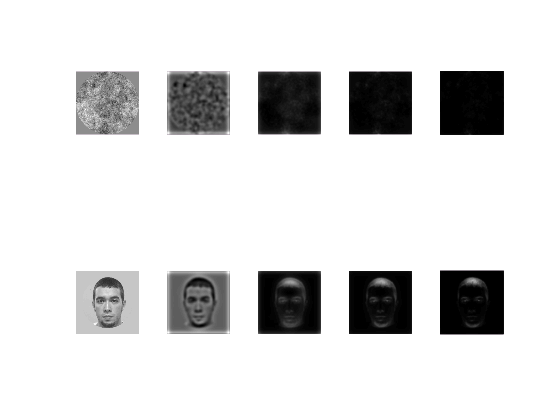

norm = @(x, y) x./(sigma + y); % x is the incoming local linear response

norm_max = @(x) x./max(x(:));

% compute linear response]
for k = 1 : 2
    rsp.lin{k}  = conv2(stim{k}, prm.rf.f_s, 'same');
    % normalization pool: mean response
    rsp.np{k} = conv2(stim{k}, prm.rf.nf_s, 'same');
    rsp.np1{k} = conv2(stim{k}, prm.rf.n1f_s, 'same');
    rsp.np2{k} = conv2(stim{k}, prm.rf.n2f_s, 'same');
    rsp.np3{k} = conv2(stim{k}, prm.rf.n3f_s, 'same');
end

% compute various form of the normalization response
for k = 1 : 2
   rsp.norm{1, k} = norm_max(norm(rsp.lin{k}, rsp.np{k})); 
   rsp.norm{2, k} = norm_max(norm(rsp.norm{1, k}, rsp.np1{k})); 
   rsp.norm{3, k} = norm_max(norm(rsp.norm{2, k}, rsp.np2{k})); 
   rsp.norm{4, k} = norm_max(norm(rsp.norm{3, k}, rsp.np3{k})); 
end

% visualize various normalization responses
figure (1), clf
subplot(2, 5, 1), imagesc(stim{1}, [0, 1]), axis square, axis off
subplot(2, 5, 6), imagesc(stim{2}, [0, 1]), axis square, axis off
for k = 1 : 4
   subplot(2, 5, k + 1), imagesc(rsp.norm{k, 1}), axis square, axis off
   subplot(2, 5, k + 6), imagesc(rsp.norm{k, 2}), axis square, axis off
end